# Genetic Algorithim in Tandem with pattern search for a PID controller accounting for implementation cost 

%0 initialisation and set up
    %0.0 plant transfer function     
        s = tf('s');
        G = (2*s^2+1)/(5*s^4+5*s^2+2*s+1);
    %0.1 desired characteristics
        rise_time=0.05      %time to reach 90 percent of input 

rise_time = 0.0500

        settling_time=0.2   %time for signal to be within settling tolerance +/-

settling_time = 0.2000

        peak_overshoot=10   %in percent copared to steady state value

peak_overshoot = 10

        settling_tolerance=2 %in percent

settling_tolerance = 2

    %0.2 Algorithim paramaters
        weighting_exponent=[1,1,1]      %rise time,settling time, peak overshoot ,

weighting_exponent =      1     1     1


        weighting_proportional=[1,1,1]  %rise time,settling time, peak overshoot 

weighting_proportional =      1     1     1


        weighting=[weighting_proportional;weighting_exponent]

weighting =      1     1     1
     1     1     1


        %if solution is weird then modify mutation factor and other options
        max_generations=18;
        population_size=30;
        elite_proportion=0.05;
        crossover_fraction=0.75;    %%exploitative
        mutation_factor=0.18;       %%eplorative
        max_num_tests=5               %no. times to run the algorithim 

max_num_tests = 5

        x_bound=1                %acceptable solution to stop re running more than sum of weighting is reasonable fitness ~>0.5 with weightings of 1 for rise time 

x_bound = 1

        cost=@(K) log2(100+sum(K)/3)-log2(100)+log2(100+sum(K.^-1)/3)-log2(100); %cost function for gain modify as required
        
        % options on the algorithim 
        options=optimoptions(@ga,"MaxGenerations",max_generations,'PopulationSize',population_size,'SelectionFcn',{@selectiontournament,4},'EliteCount',ceil(elite_proportion*population_size),'CrossoverFraction',crossover_fraction,'CrossoverFcn',@crossoverheuristic,'MutationFcn',{@mutationadaptfeasible,mutation_factor});
        x=inf;

%1 algorithim implementation 
    for i=1:max_num_tests    %for the number of tests
        
        %1.1 execute combined algoritthim
            [K_test,x_test]=PID_Best(G,rise_time,settling_time,peak_overshoot,settling_tolerance,options,weighting,cost);
        %1.2 if new test is better than old overwrite data
            if x_test<x
                K=K_test;
                x=x_test;
            end
        %1.3 if the new test is sufficiently good stop re running
            if x<x_bound
                number_of_iterations=i
                break
            end
    end

Optimization terminated: maximum number of generations exceeded.
Maximum number of iterations exceeded: increase options.MaxIterations.
Optimization terminated: maximum number of generations exceeded.
Maximum number of iterations exceeded: increase options.MaxIterations.


number_of_iterations = 2


%2 testing output solution 
    %2.1 defining solution 
        C=K(1)+K(2)/s+K(3)*s    %controller transfer function 

C =
 
  105.5 s^2 + 95.15 s + 1.759
  ---------------------------
               s
 
Continuous-time transfer function.



        H=feedback(C*G,1)       %closed loop transfer function 

H =
 
      211 s^4 + 190.3 s^3 + 109 s^2 + 95.15 s + 1.759
  -------------------------------------------------------
  5 s^5 + 211 s^4 + 195.3 s^3 + 111 s^2 + 96.15 s + 1.759
 
Continuous-time transfer function.



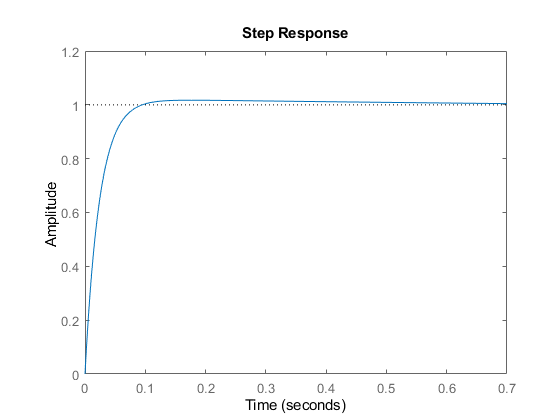

    %2.2 simulation solution 
        step(H)                 %step response

        stepinfo(H)             %step paramaters

ans = struct with fields:
        RiseTime: 0.0491
    SettlingTime: 0.0780
     SettlingMin: 0.9042
     SettlingMax: 1.0172
       Overshoot: 1.7195
      Undershoot: 0
            Peak: 1.0172
        PeakTime: 0.1763


    %2.3 final fitness value
        fitness=pidtest(G,rise_time,settling_time,peak_overshoot,settling_tolerance,weighting,K,cost)

fitness = 0.7476

        function [K,x]=PID_Best(G,rise_time,settling_time,peak_overshoot,settling_tolerance,options,weighting,cost)

        fitness_function=@(K)pidtest(G,rise_time,settling_time,peak_overshoot,settling_tolerance,weighting,K,cost);

[K,~] = ga(fitness_function,3,-1*eye(3),zeros(3,1),[],[],[],[],[],[],options);

[K,x] = patternsearch(fitness_function,K,-1*eye(3),-1e-6*ones(3,1));

end

function fitness=pidtest(G,rise_time,settling_time,peak_overshoot,settling_tolerance,weighting,K,cost)
    s=tf('s');
    if ~all(K)
        fitness=inf;  %dc gain of zero error
    else
        C=K(1)+K(2)/s+K(3)*s;
        H=feedback(C*G,1);                 %closed loop tf
        Tau=rise_time+settling_time+1;      %time period
        [Y,T]=step(H,[0:Tau/1000:5*Tau]);  %simulate the response for 5 time periods
        fitness=eval_fitness(Y,T,rise_time,settling_time,peak_overshoot,settling_tolerance,weighting)+cost(K);
        
        if isnan(fitness) %%if for somoe reason fitness is a NAN then fitness=inf
            fitness=inf;
        end
    end
    
end
        
function fitness=eval_fitness(Y,T,rise_time,settling_time,peak_overshoot,settling_tolerance,weighting)
        fit1=weighting(1,3)*fit_segment(Y,T,0,rise_time,0,1+peak_overshoot/100)^weighting(2,3);
        fit2=weighting(1,2)*fit_segment(Y,T,rise_time,settling_time,0.9,1+peak_overshoot/100)^weighting(2,1);
        fit3=weighting(1,2)*fit_segment(Y,T,settling_time,T(end),1-settling_tolerance/100,1+settling_tolerance/100)^weighting(2,2);
        fitness=fit1+fit2+fit3;
    end
    
    function fit=fit_segment(Y,T,t_min,t_max,y_min,y_max)
        indexes=(T>t_min & T<=t_max);
        y=Y(indexes);
        y=(y-y_max).*heaviside(y-y_max)+(y_min-y).*heaviside(y_min-y);
        fit=trapz(y);
    end
    
